taxiData = importTaxiData("yellow_tripdata_2015-05.csv");
taxiData = addTimeOfDay(taxiData)

taxiData = 255761×22 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    Duration    AveSpeed    TimeOfDay
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________<

[trainedModel, validationRMSE] = trainLinearRegressionModel(taxiData)

trainedModel = struct with fields:
           predictFcn: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Distance'  'DropoffLat'  'DropoffLon'  'PickupLat'  'PickupLon'  'TimeOfDay'}
          LinearModel: [1×1 LinearModel]
                About: 'This struct is a trained model exported from Regression Learner R2021b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 6.8989

[trainedModel, validationRMSE] = trainCoarseTree6RegressionModel(taxiData)

trainedModel = struct with fields:
           predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Distance'  'DropoffLat'  'DropoffLon'  'PickupLat'  'PickupLon'  'TimeOfDay'}
       RegressionTree: [1×1 RegressionTree]
                About: 'This struct is a trained model exported from Regression Learner R2021b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 5.0503

taxiJun = importTaxiData("yellow_tripdata_2015-06.csv");

FarePerMile = taxiJun.Fare ./ taxiJun.Distance;

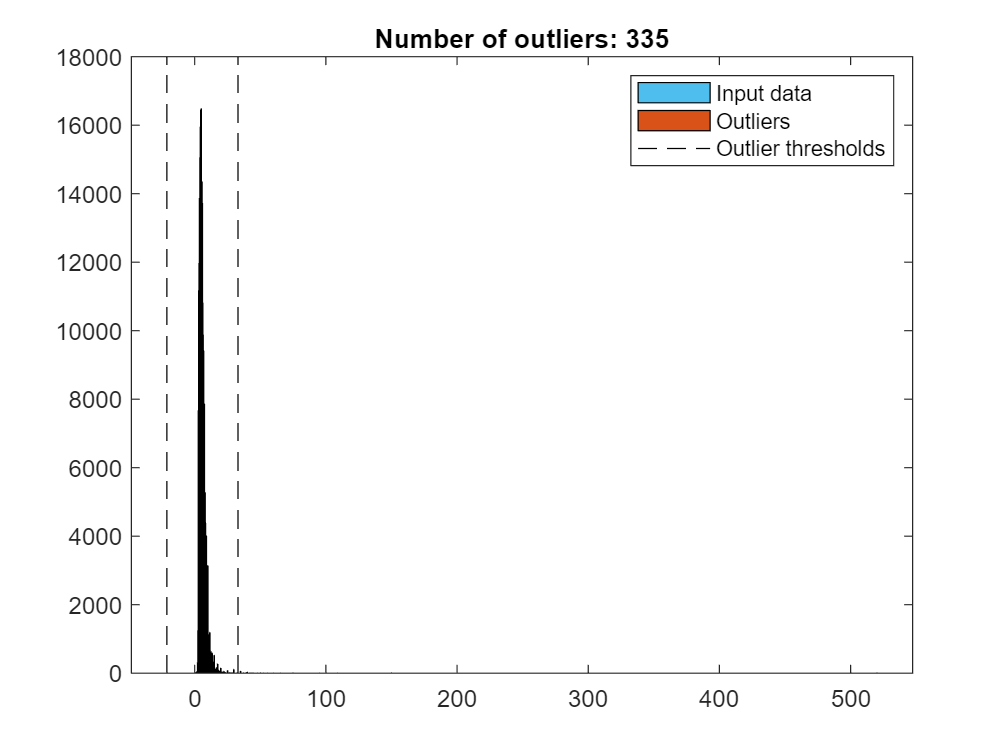

% Remove outliers
[cleanedData,outlierIndices] = rmoutliers(FarePerMile,"mean",...
    "ThresholdFactor",6);

% Display results
clf

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(FarePerMile,"mean",...
    "ThresholdFactor",6);
[~,binEdges] = histcounts(FarePerMile);
binEdges = unique([binEdges thresholdLow thresholdHigh]);
binEdges = binEdges(isfinite(binEdges));
histogram(FarePerMile,"BinEdges",binEdges,"FaceColor",[77 190 238]/255,...
    "FaceAlpha",1,"DisplayName","Input data")
hold on

% Plot outliers
histogram(FarePerMile(outlierIndices),"BinEdges",binEdges,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Plot outlier thresholds
plot([thresholdLow*[1 1] NaN thresholdHigh*[1 1]],[ylim missing ylim],"k--",...
    "DisplayName","Outlier thresholds")

hold off
legend

clear thresholdLow thresholdHigh binEdges
round(max(cleanedData),2)

ans = 32.6100

taxiJun = addTimeOfDay(taxiJun);
taxiJun = addDayOfWeek(taxiJun);
% taxiRange = prctile(FarePerMile,[1 99]);
% taxiRange = FarePerMile(FarePerMile>=taxiRange(1) & FarePerMile<=taxiRange(2));
% histogram(taxiRange)